# Result Analyze

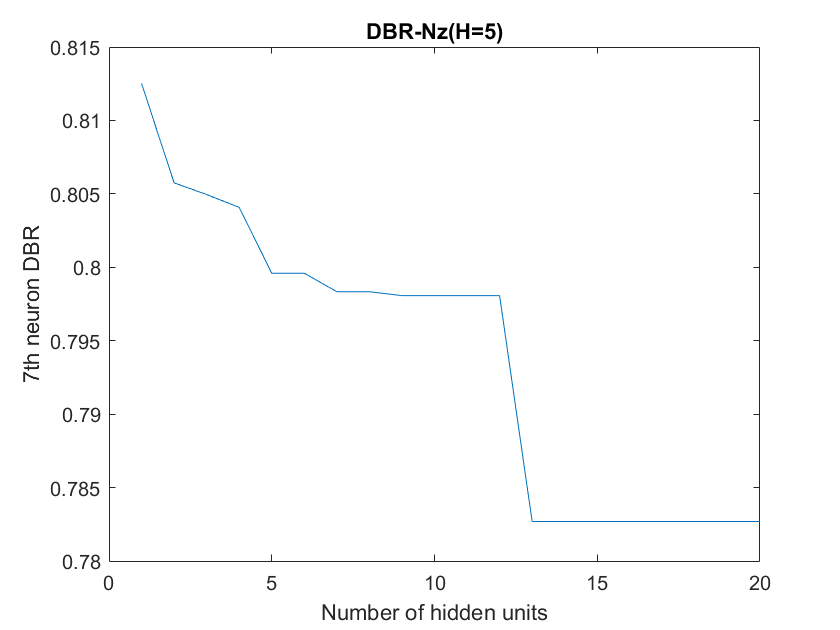

close all;clear;clc;
addpath models/
load data/data_rat010_0615_spike_train_selected_with_delay.mat
load results/GLM_explore_H_new.mat
load results/GLM_sec_explore_H_new.mat
load results/ANN_explore_Nz_new.mat
% load results/ANN_explore_H.mat

% ANN Nz-DBR
ANN_Nz_DBR = zeros(1,20);
Nzlist = 1:20;
bestDBR = Inf;
for Nz=Nzlist
  for i=1:ceil(Nz/5)*16
      bestDBR = min(ANN_explore_Nz(Nz,i).DBR, bestDBR);
  end
  ANN_Nz_DBR(Nz)=bestDBR;
end
figure(1)
plot(Nzlist, ANN_Nz_DBR)
xlabel("Number of hidden units")
ylabel("7th neuron DBR")
title("DBR-Nz(H=5)")

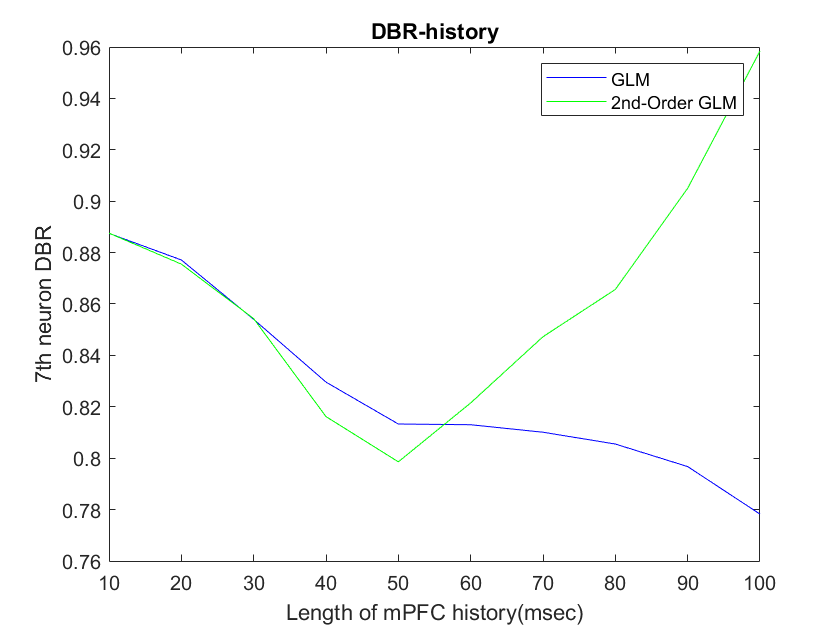

% get DBRs from differnt model result
GLM_sec_DBR = zeros(1,10);
GLM_DBR = zeros(1,10);
% ANN_DBR = ones(1,10)*10;
for i=1:10
  GLM_DBR(i)     = GLM_explore_H(i).DBR;
  GLM_sec_DBR(i) = GLM_sec_explore_H(i).DBR;
%   for j=1:100
%     ANN_DBR(i) = min(ANN_DBR(i), ANN_explore_H(i,j).DBR);
%   end
end
% plot DBR-history result
figure(2)
plot(10:10:100, GLM_DBR, 'b')
hold on
plot(10:10:100, GLM_sec_DBR, 'g')
% plot(10:10:100, ANN_DBR, 'm')
hold off
legend("GLM", "2nd-Order GLM")%, "Staged Point-Process(Nz=10)")
xlabel("Length of mPFC history(msec)")
xlim([10 100])
ylabel("7th neuron DBR")
title("DBR-history")

Take history = 80msec, kernel size = 1s

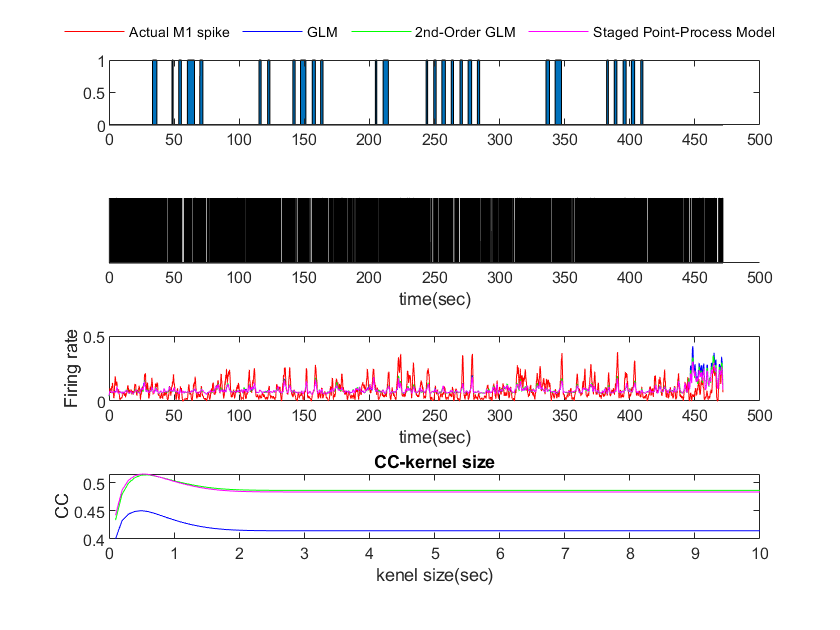

H=5;
% get GLM params & test result
W     = GLM_explore_H(H).W;
M1Idx = GLM_explore_H(H).M1Idx;
[~,~,~,~,~,testX,~,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),H);
GLMtestLambdaYpre = GLMmodel(testX, W);
GLMccList = zeros(1, 1000/10);
% smooth result
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLMccList(kernelSize/10) = cc(2);
end

% 2nd Order GLM
W     = GLM_sec_explore_H(H).W;
M1Idx = GLM_sec_explore_H(H).M1Idx;
[~,~,~,~,~,testX,~,~,testY,~,~,testEvent] = splitDataAdvance(2,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),H);
GLMsectestLambdaYpre = GLMmodel(testX, W);
GLM_sec_ccList = zeros(1, 1000/10);
% smooth
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLM_sec_ccList(kernelSize/10) = cc(2);
end

% ANN
bestDBR = Inf;
for i=1:48
  if (ANN_explore_Nz(13,i).DBR<bestDBR)
    bestDBR = ANN_explore_Nz(13,i).DBR;
    W = ANN_explore_Nz(13,i).W;
    M1Idx = ANN_explore_Nz(13,i).M1Idx;
  end
end
[~,~,~,~,~,testX,~,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),H);
[~, Nx] = size(testX);
ANNtestLambdaYpre = ANNmodel(testX, W, Nx, 13);
ANNccList = zeros(1, 1000/10);
% smooth
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  ANNccList(kernelSize/10) = cc(2);
end

% optimal smooth kernel size result
kernelSize = 50;
smoothedLambda = gaussianSmooth(testY, kernelSize);
smoothedGLMLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
smoothedGLMsecLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
smoothedANNLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);

% take part of result for display
spikeLength = length(testY);
index = 1:spikeLength;
t = index/100;
figure(3)
% real spike
subplot(4,1,2)
area(t, testY(index))
xlabel("time(sec)")
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
% smoothed results
subplot(4,1,3)
h{1} = plot(t, smoothedLambda(index), 'r');
hold on
h{2} = plot(t, smoothedGLMLambdaPre(index), 'b');
h{3} = plot(t, smoothedGLMsecLambdaPre(index), 'g');
h{4} = plot(t, smoothedANNLambdaPre(index), 'm');
hold off
xlabel("time(sec)")
ylabel("Firing rate")
% cc analyze
subplot(4,1,4)
plot(0.1:0.1:10, GLMccList, 'b')
hold on
plot(0.1:0.1:10, GLM_sec_ccList, 'g')
plot(0.1:0.1:10, ANNccList, 'm');
hold off
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size")
legend([h{1}; h{2}; h{3}; h{4}], "Actual M1 spike", "GLM", "2nd-Order GLM", "Staged Point-Process Model", ...
  "Position",[0.5  0.95  0  0], "Box","off", "Orientation","horizontal")
% legend([h{1}; h{2}; h{3}], "Actual M1 spike", "GLM", "2nd-Order GLM", ...
%   "Position",[0.5  0.95  0  0], "Box","off", "Orientation","horizontal")
subplot(4,1,1)
area((1:length(testEvent))/100, testEvent)

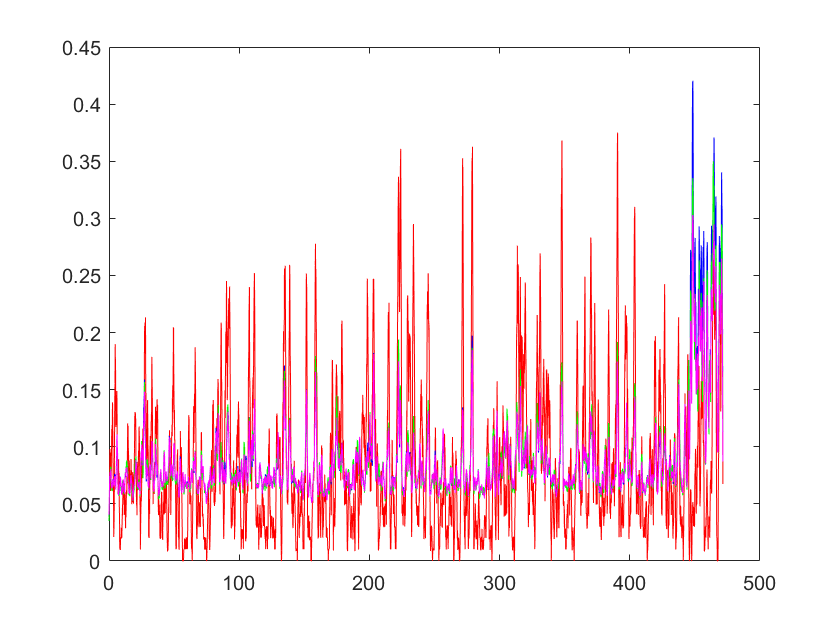

figure
h{1} = plot(t, smoothedLambda(index), 'r');
hold on
h{2} = plot(t, smoothedGLMLambdaPre(index), 'b');
h{3} = plot(t, smoothedGLMsecLambdaPre(index), 'g');
h{4} = plot(t, smoothedANNLambdaPre(index), 'm');
hold off

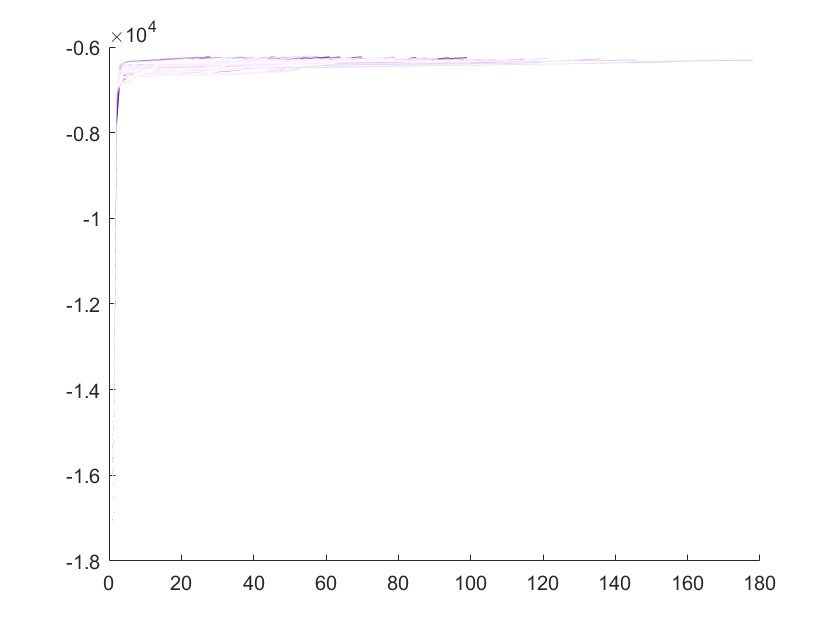

figure
hold on
for i=1:800
  [Nz, idx] = getParamIndex(i);
  LHistory = ANN_explore_Nz(Nz,idx).LHistory;
  LHistory(LHistory==0) = nan;
  h=plot(LHistory);
  set(h, 'color', [i/800, i*i/640000, sqrt(i)/sqrt(800)])
end
hold off

% bestL = zeros(1, 20);
% for i=1:20
%   LvalList = zeros(1, 20);
%   for j=1:20
%     LvalList(j) = ANN_explore_Nz(i,j).Lval;
%   end
%   bestL(i) = min(LvalList);
% end
% plot(bestL)
% bestDBR = zeros(1, 20);
% for i=1:20
%   dbrList = zeros(1, 20);
%   for j=1:20
%     dbrList(j) = ANN_explore_Nz(i,j).DBR;
%   end
%   bestDBR(i) = min(dbrList);
% end
% plot(bestDBR)